# COCO-API

cuixingxing150@gmail.com

 2021.8.11

## **OverView**

       As we all know, the [COCO2014/2017](https://cocodataset.org/#home) dataset is widely used for object detection, instance segmentation, image description, key point detection, panoramic segmentation and many other tasks, the official has provided cocoapi's python, matlab, lua language interface, but in matlab using the interface provided by the program is very poor readability, not easy to intuitively clear, the use of people This program makes full use of the characteristics of the table type to enrich the expression of coco datasets, with only about 100 lines of code to achieve the "instances", "keypoints" ,"captions" level of API, without any third-party libraries, can be customized to modify the API, code readability.

      众所周知，[COCO2014/2017](https://cocodataset.org/#home)数据集被广泛用于目标检测、实例分割、图像描述、关键点检测、全景分割等多种任务，官方已提供cocoapi的python、matlab、lua语言的接口，但在matlab中使用其提供的接口程序可读性非常差，不易直观清晰，使用的人较少，本程序充分利用table类型的特性，丰富展示coco数据集的表达，仅用100行左右代码实现了“instances”、“keypoints”、“captions”级别的API，无需任何第三方库，可二次自定义修改API，代码可读性强。

## **Syntax**

**[allCOCOdata,cocoDatastore,cocoNames] = cocoInstancesAPI(imagesDir,annotationFile,categoryNames)**

**功能**：优雅的实现coco2014，coco2017数据集instances新接口 

 **输入**：

        imagesDir，string类型，1*1大小，输入COCO图像文件根目录

        annotationFile，string类型，1*1大小，与之对应的标注json文件

        categoryNames，（可选项）string类型，1*N大小，物体类别，默认所有类别

** 输出**：

        allCOCOdata， table类型，所有带有标注的完整信息，每行代表一副图像

        cocoDatastore，TransformedDatastore object，可就地迭代对象

        cocoNames，categorical类型，80个类别

** [allCOCOdata,cocoDatastore,keyPtsNames,skeleton] = cocoKeyPointsAPI(imagesDir,annotationFile)**

** 功能**：优雅的实现coco2014，coco2017数据集keypoints新接口

 **输入**：

     imagesDir，string类型，输入COCO图像文件根目录

     annotationFile，string类型，与之对应的标注json文件

** 输出**：

     allCOCOdata， table类型，所有带有标注的完整信息，每行代表一副图像

     cocoDatastore，TransformedDatastore object，可就地迭代对象

     keyPtsNames，categorical类型数组，长度为17，分别为人体各个部位id顺序名字

    skeleton，double类型数组，M*2大小，人体部位各个id连接情况，第一列与第二列id进行连接

**[allCOCOdata,cocoDatastore] = cocoCaptionsAPI(imagesDir,annotationFile)**

**功能**：优雅的实现coco2014，coco2017数据集Captions新接口

**输入**：

     imagesDir，string类型，输入COCO图像文件根目录

    annotationFile，string类型，与之对应的标注json文件

**输出**：

     allCOCOdata， table类型，所有带有标注的完整信息，每行代表一副图像

    cocoDatastore，TransformedDatastore object，可就地迭代对象

## Requirements

- MatlabR2020b or higher

- [](https://cocodataset.org/#download)[coco2014 or 2017 datasets (images and annotations)](https://cocodataset.org/#download)

## **How to use**

一般做object detection/segmention/keypoints/captions,训练任务都会用到可迭代的datasets，比如对上述三类API返回数据cocoDatastore进行[迭代使用](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transformeddatastore.html)**，**read会从内存中读取部分数据，读取的数据直观上应当有以下返回形式数据格式：

data = [read](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.read.html)(cocoDatastore)

根据不同任务的API，返回元胞数组data中的元素有如下直观形式。

- RGB images (H x W x 3)

- Bounding boxes (NumObjects x 4,  arranged as [x y w h])

- Labels (NumObjects x 1), categorical

- Masks (H x W x NumObjects) 

- KeyPoints (17×3×NumObjects)

- Captions(NumSentences x 1 cell array)

## Example1, instance

% coco path
imagesDir = '\\192.168.1.103\dataSets\coco2017\val2017\val2017';
annotationFile = '\\192.168.1.103\dataSets\coco2017\annotations_trainval2017\annotations\instances_val2017.json';
yourNames = ["dog","cat"]; % optional
% coco-api
[allCOCOdata,cocoDatastore,coconames] = cocoInstancesAPI(imagesDir,...
    annotationFile,yourNames);

head(allCOCOdata) % preview,Get top rows of table

ans = 8×13 table
    image_id    license         file_name                                   coco_url                             height    width         date_captured                                     flickr_url                                GroupCount     segments     iscrowd                     bbox                      category_id
    ________    _______    ____________________    __________________________________________________________    ______    _____    _______________________    __________________________________________________________________    __________    __________    _______    _______________________________________    ___________
      1675         1       {'000000001675.jpg'}    {'http://images.cocodataset.org/val2017/000000001675.jpg'}     480       640     {'2013-11-18 00:14:32'}    {'http://farm1.staticflickr.com/104/301990977_42713fd7f4_z.jpg'  }        1         {1×1 cell}     {[0]}     {[             0 14.0100 640 293.5600]}      {[17]}   
      4795    

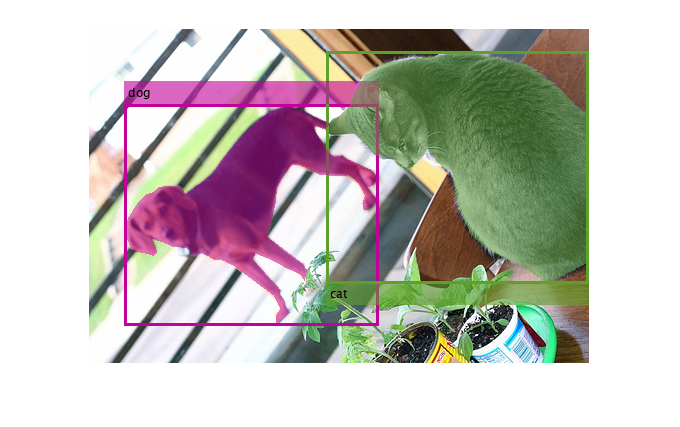

colormap = randi(255,length(coconames),3);
cocoDatastore = shuffle(cocoDatastore); % random 
while cocoDatastore.hasdata()
    data = read(cocoDatastore);
    img = data{1};  % origin image(H×W×C)
    bboxs = data{2}; % Bounding boxes (NumObjects x 4,  arranged as [x y w h])
    labels = data{3};% Labels (NumObjects x 1), categorical
    masks = data{4}; % Masks (H x W x NumObjects) 
   
    colors = colormap(arrayfun(@(x)find(x==coconames),labels),:);
    draw = insertObjectAnnotation(img,'rectangle',bboxs,labels,...
        'LineWidth',3,...
        'Color',colors);
    for i = 1:size(masks,3)
        draw = labeloverlay(draw,masks(:,:,i),...
            'Colormap',colors(i,:)/255,...
            'Transparency' , 0.5);
    end
    
    imshow(draw)
    break;
end

## Example2, keypoints

imagesDir='\\192.168.1.103\dataSets\coco2017\val2017\val2017';
annotationFile = '\\192.168.1.103\dataSets\coco2017\annotations_trainval2017\annotations\person_keypoints_val2017.json';
[allCOCOdata,cocoDatastore,keyPtsNames,skeleton] = ...
    cocoKeyPointsAPI(imagesDir,annotationFile);
head(allCOCOdata) % preview,Get top rows of table

ans = 8×12 table
    image_id    license         file_name                                   coco_url                             height    width         date_captured                                     flickr_url                                GroupCount     segments                       bbox                        keypoints    
    ________    _______    ____________________    __________________________________________________________    ______    _____    _______________________    __________________________________________________________________    __________    ___________    __________________________

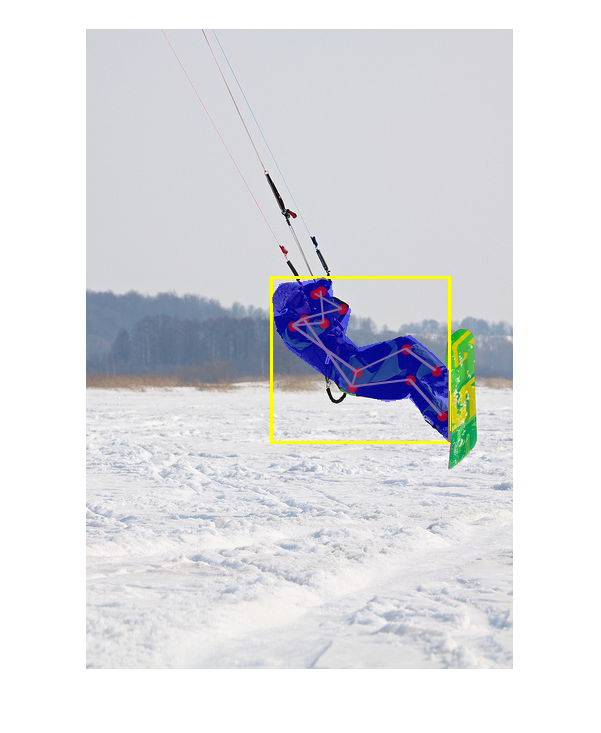


cocoDatastore = shuffle(cocoDatastore); % random
while cocoDatastore.hasdata()
    data = read(cocoDatastore);
    img = data{1};   % origin image(H×W×C)
    bboxs = data{2}; % Bounding boxes (NumObjects x 4,  arranged as [x y w h])
    masks = data{3}; % Masks (H x W x NumObjects)
    keyPts = data{4}; % KeyPoints (17×3×NumObjects)
    
    % plot
    draw = insertObjectAnnotation(img,'rectangle',bboxs,"",...
        'LineWidth',3);
    for i = 1:size(masks,3)
        draw = labeloverlay(draw,masks(:,:,i));
    end
    draw = drawSkeleton(draw,keyPts,skeleton);
    
    imshow(draw)
    break;
end

## Example3,captions

imagesDir = '\\192.168.1.103\dataSets\coco2017\val2017\val2017';
annFile = '\\192.168.1.103\dataSets\coco2017\annotations_trainval2017\annotations\captions_val2017.json';
[allCOCOdata,cocoDatastore] = cocoCaptionsAPI(imagesDir,annFile);
head(allCOCOdata) % preview,Get top rows of table

ans = 8×10 table
    image_id    license         file_name                                   coco_url                             height    width         date_captured                                     flickr_url                                GroupCount     captions 
    ________    _______    ____________________    __________________________________________________________    ______    _____    _______________________    __________________________________________________________________    __________    __________
      139          2       {'000000000139.jpg'}    {'http://images.cocodataset.org/val2017/000000000139.jpg'}     426       640     {'2

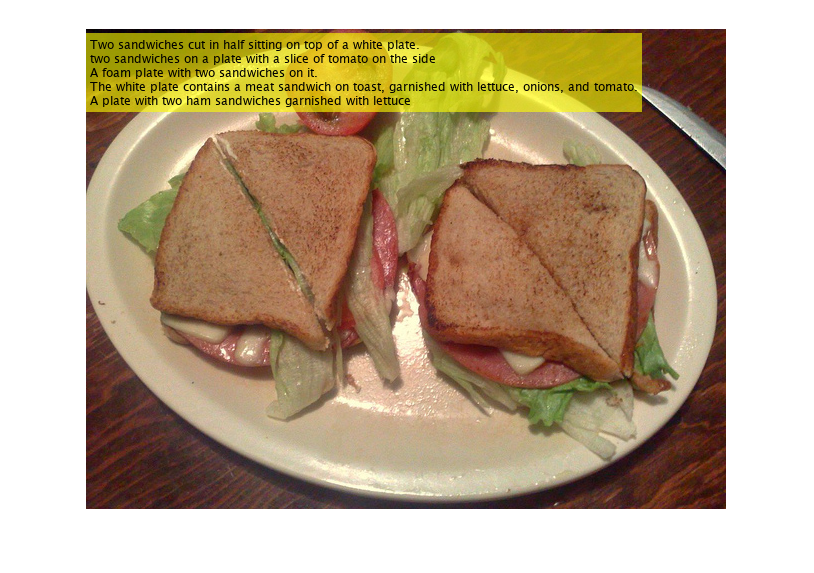

cocoDatastore = cocoDatastore.shuffle();
while cocoDatastore.hasdata()
    data = read(cocoDatastore);
    img = data{1};   % origin image(H×W×C)
    captions = data{2}; % captions (NumSentences x 1 cell array)

    % caption
    draw = insertText(img,[1,5],strjoin(captions,'\n'));
    imshow(draw);
    break;
end

## SupportFunction

function drawRGB = drawSkeleton(image,keyPts,skeleton)
% 功能：在输入图像image上绘制人体骨架图,只绘制标注过的点线
% 输入：
%    image
%           大小为H*W*C，输入图像
%    keyPts
%            double类型数组，大小为17*3*NumObjects; 17个点，3表示[x,y,flag]，
%            flag=0,表示这个关键点没有标注（这种情况下x=y=flag=0），flag为1时
%            表示这个关键点标注了但是不可见（被遮挡了），flag为2时表示这个关键
%            点标注了同时也可见.
%   skeleton
%           double类型数组，大小为M*2,表示coco中17个点连接情况，数据表示ID序号
% 输出：
%     drawRGB
%           大小为H*W*C，输出图像
%
% author:cuixingxing
% cuixingxing150@gmail.com
% 2021.8.11
%
arguments
    image
    keyPts (17,3,:) double
    skeleton (:,2) double
end
drawRGB = image;
Radus = 5;
numObjs = size(keyPts,3);
colormaps = randi(255,numObjs,3);
for i = 1:numObjs
    currentKPts = keyPts(:,:,i);% 17*3, [x,y,flag]
    validIdx = currentKPts(:,3)~=0;
    
    validKPts = currentKPts(validIdx,:);
    radius = Radus*ones(sum(validIdx),1);
    drawRGB = insertShape(drawRGB,...
        'FilledCircle',[validKPts(:,1:2),radius],...
        'Color','red');
    
    validID = find(validIdx);
    connectionValidID = ismember(skeleton(:,1),validID)&...
        ismember(skeleton(:,2),validID);
    connectionValid = skeleton(connectionValidID,:);
    x1 = currentKPts(connectionValid(:,1),1);
    y1 = currentKPts(connectionValid(:,1),2);
    x2 = currentKPts(connectionValid(:,2),1);
    y2 = currentKPts(connectionValid(:,2),2);
    lines = [x1,y1,x2,y2];
    drawRGB = insertShape(drawRGB,'Line',lines,...
        'Color',colormaps(i,:),...
        'LineWidth',2);
end
end


## Reference

[1] [coco-datasets](https://cocodataset.org/)

[2] [COCO数据集的标注格式](https://zhuanlan.zhihu.com/p/29393415)